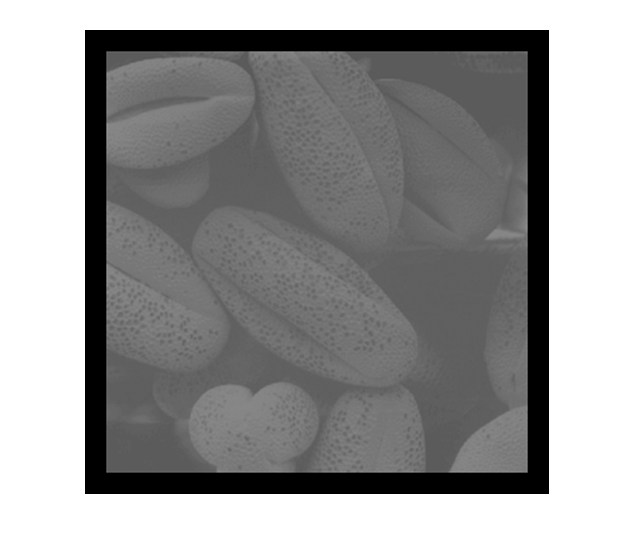

sample = rgb2gray(imread('grain.png'));
imshow(sample);

[length,width] = size(sample);
count = zeros(1,256);
for i = 1:length
    for j = 1:width
        count(1,sample(i,j)+1) = count(1,sample(i,j)+1)+1;
    end
end


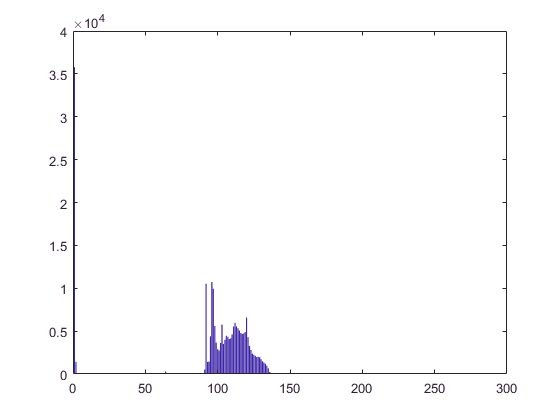

bar(count);

new = zeros(1,256);
for i = 1:length
    for j = 1:width
        if sample(i,j)<80
            sample(i,j) = sample(i,j)/2;
        elseif sample(i,j)>80 && sample(i,j)<160
            sample(i,j) = sample(i,j)*2-120; 
        else
            sample(i,j) = sample(i,j)*0.58-107.36; 
        end
            
        new(1,sample(i,j)+1) = new(1,sample(i,j)+1)+1;
    end
end

imshow(sample);

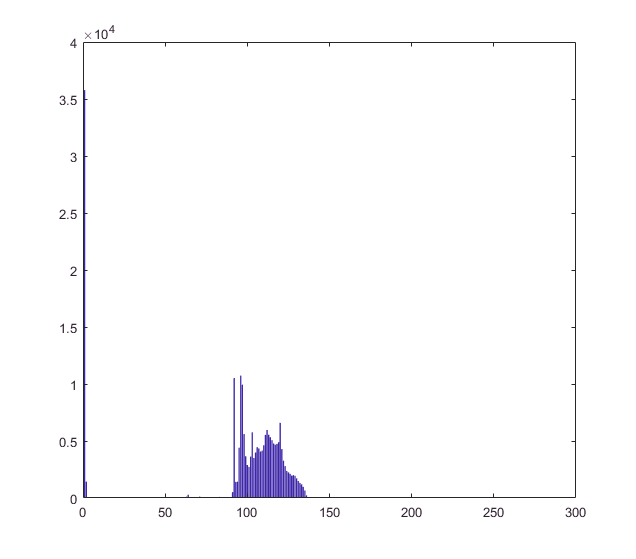

bar(new);